experiment1

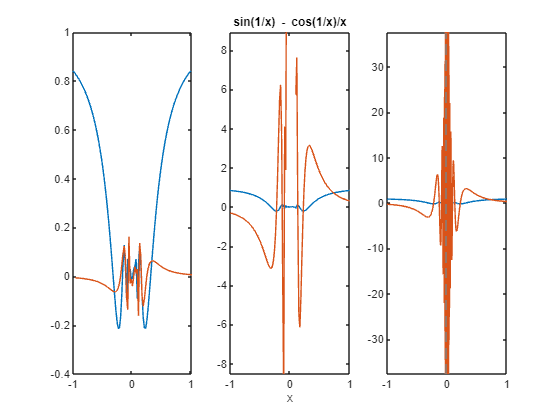

f = @(x)x.*sin(1./x);
syms x
g = x.*sin(1./x);
Data = linspace(-1,1);
Y1 = f(Data);
clf
subplot(1,3,1)
plot(Data,Y1)
hold on
plot(Data(2:end)+diff(Data),diff(Y1))
subplot(1,3,2)
ezplot(g,[-1,1])
ylim(-1,1)
hold on
ezplot(diff(g),[-1,1])
subplot(1,3,3)
fplot(g,[-1,1])
hold on
fplot(diff(g),[-1,1])

quadraticSolve(1,1,4)

ans =   -0.5000 - 1.9365i
  -0.5000 + 1.9365i


quadraticSolve(1,4,4)

ans = -2

quadraticSolve(1,3,2)

ans =     -2
    -1


quadraticSolve(0,1,4)

Error using lab2>quadraticSolve
a can't be zero!

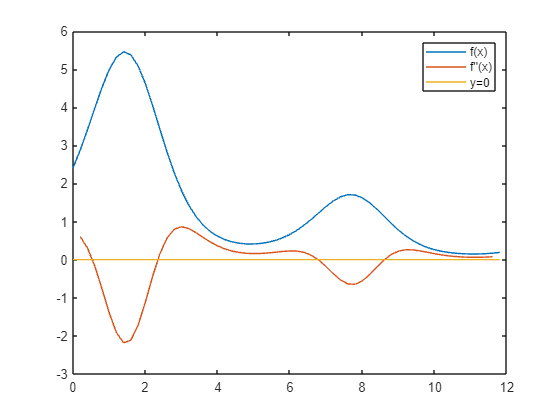

Data = readmatrix('随堂实验题2_data.xlsx');
Data = [Data(:,2:3);Data(:,5:6);Data(:,8:9)];
clf
plot(Data(:,1),Data(:,2))
hold on
plot(Data(2:end-1,1),diff(Data(:,2),2)*10)
fplot(0,[Data(1,1),Data(end,1)])
legend('f(x)','f''''(x)','y=0')

We can see the intersections of the red curve and the yellow line

function [X]=quadraticSolve(a,b,c)
if a==0
    error('a can''t be zero!')
else
    syms x
    eqn = a*x^2 + b*x + c == 0;
    X = double(unique(solve(eqn)));
end
end